init_unfold


Starting unfold toolbox.
Adding subfolders and other toolboxes to path...
Done.


# Plotting Single-Trial ERPimages

% We simulate data with a stimulus onset of two types + a buttonpress
EEG = tutorial_simulate_data('erpimage');

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Event resorted by increasing latencies.


This design has **Stimulus** and **Buttonpress**. The stimulus has two levels: **face** and **house**. There is only overlap between stimulus and buttonpress, but not between buttonpress and subsequent stimulus..

cfgDesign = [];
cfgDesign.eventtypes = {'stimulus','buttonpress'};
cfgDesign.formula = {'y ~ 1+ cat(stimulusType)','y~1'};

EEG = uf_designmat(EEG,cfgDesign);

Multiple events with separate model-formula detected
Modeling 185 event(s) of [stimulus] using formula: y~1+stimulusType 
Modeling 185 event(s) of [buttonpress] using formula: y~1 


cfgTimeexpand = [];
cfgTimeexpand.timelimits = [-.3,1.5];

EEG = uf_timeexpandDesignmat(EEG,cfgTimeexpand);


uf_timeexpandDesignmat(): Timeexpanding the designmatrix...
...done


EEG= uf_glmfit(EEG);


uf_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 1 (of 1 electrodes in total)... 30 iterations, took 0.0s
 LMfit finished 


After fitting the EEG, we can visualize the ERPimages

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event , 370 epochs found
Sorting erpimage from event  forwards by field latency
Plotting input data as 370 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
100.00% of the trials (i.e., 370 out of 370) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 370, 25th ptile: 370, Median: 370, 75th ptile: 370, Max: 370

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-2.35367,2.35367].
Data will be plotted between -300 and 1495 ms.


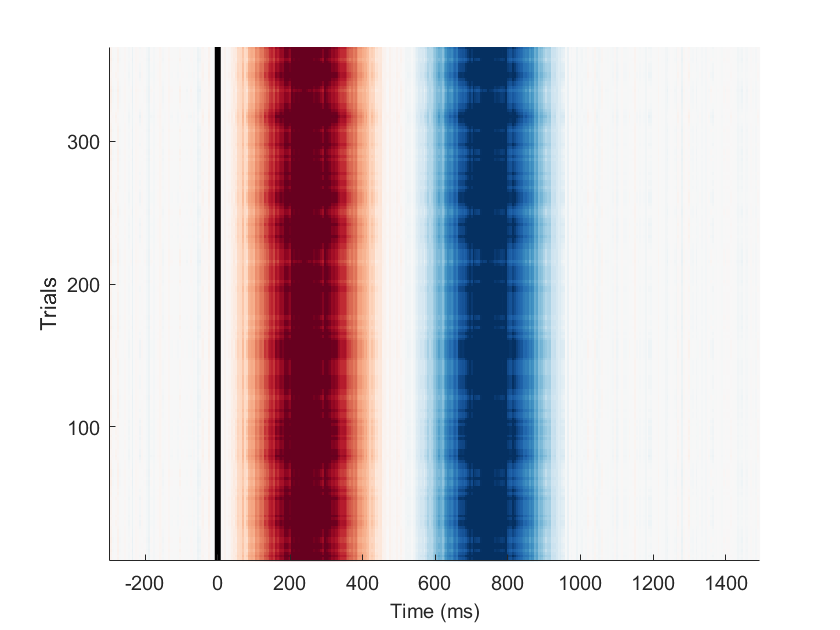

Output data will be 360 frames by 361 smoothed trials.
Outtrials: 6.00 to 366.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'channel',1)

By default the erpimage is not sorted and the plot is depicting the **overlap-corrected** estimate.

### CFG-Trick

to increase legibility, I am going to introduce some plotting options to each plot by constructing a cell-array suitable to pass to each of the following erpimages

cfg = []


cfg =

     []



cfg.channel = 1

cfg = struct with fields:
    channel: 1


cfg.figure = 1

cfg = struct with fields:
    channel: 1
     figure: 1


cfg.caxis = [-5,5]

cfg = struct with fields:
    channel: 1
     figure: 1
      caxis: [-5 5]


cfg.alignto = 'stimulus'

cfg = struct with fields:
    channel: 1
     figure: 1
      caxis: [-5 5]
    alignto: 'stimulus'


cfg = [fieldnames(cfg),struct2cell(cfg)].';
cfg(:)

ans = 8×1 cell array
    {'channel' }
    {[       1]}
    {'figure'  }
    {[       1]}
    {'caxis'   }
    {1×2 double}
    {'alignto' }
    {'stimulus'}


## Raw ERPimage

We can also look at the raw ERPimage. This is the same as running eeg_erpimage on your typical epoched data. As you can see, compared to the overlap-corrected model-estimate, we have much more noise included here.

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event stimulus, 185 epochs found
Sorting erpimage from event stimulus forwards by field latency
Plotting input data as 185 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
100.00% of the trials (i.e., 185 out of 185) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 185, 25th ptile: 185, Median: 185, 75th ptile: 185, Max: 185

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-5,5].
Data will be plotted between -300 and 1495 ms.


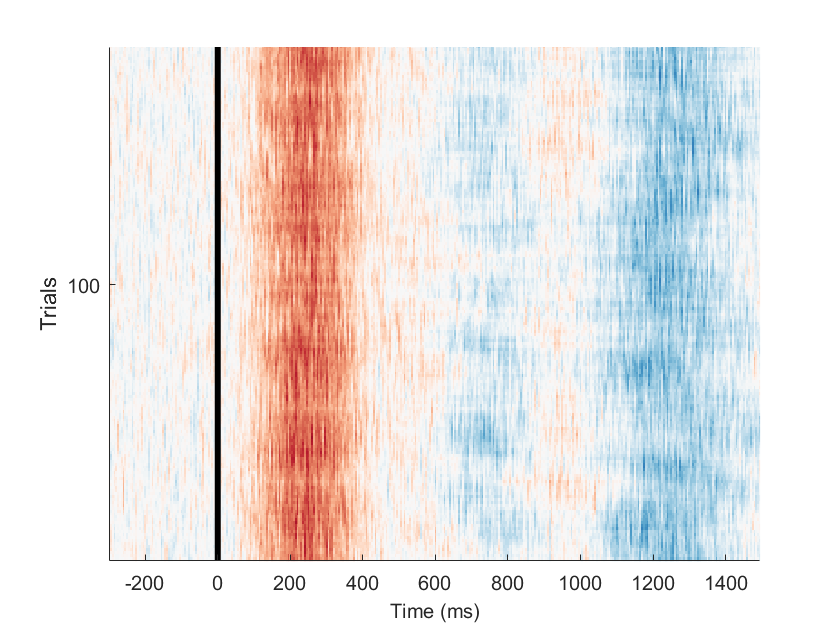

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'type','raw',cfg{:})

## Sorting trials by condition

Now we can start sorting trials by condition, for instance here by stimulus type.

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event stimulus, 185 epochs found
Sorting erpimage from event stimulus forwards by field stimulusType
Plotting input data as 185 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
100.00% of the trials (i.e., 185 out of 185) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 90, 25th ptile: 90, Median: 93, 75th ptile: 95, Max: 95

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-5,5].
Data will be plotted between -300 and 1495 ms.


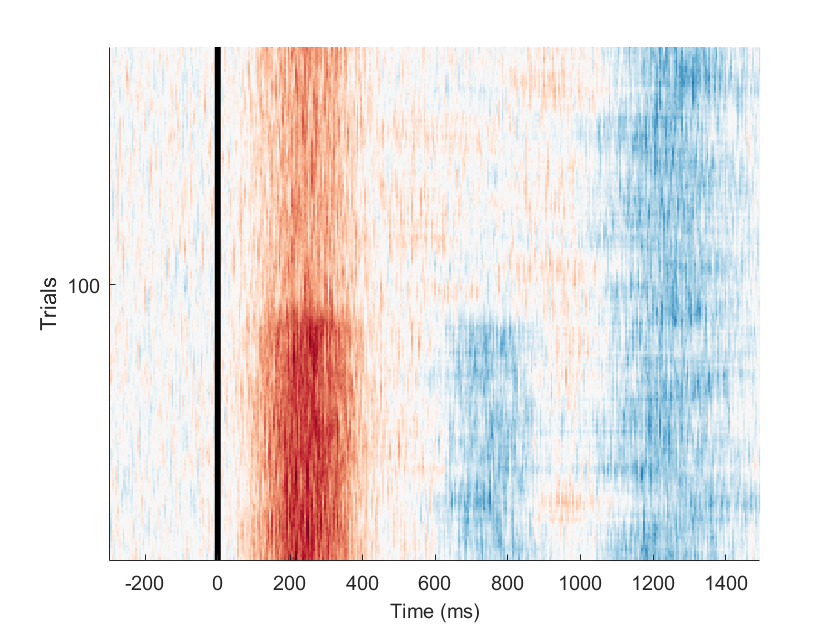

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'type','raw','sort_by','stimulusType',cfg{:})

We directly see, that one condition seems to have a smaller effect than the other (based on the "P2" at 200ms. But towards the end of the epoch there is another interesting pattern. Let's investigate this further. We switch back the `type` to `modelled` in order to see what the overlap contributes to this pattern.

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event stimulus, 185 epochs found
Sorting erpimage from event stimulus forwards by field stimulusType
Plotting input data as 185 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
100.00% of the trials (i.e., 185 out of 185) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 90, 25th ptile: 90, Median: 93, 75th ptile: 95, Max: 95

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-5,5].
Data will be plotted between -300 and 1495 ms.


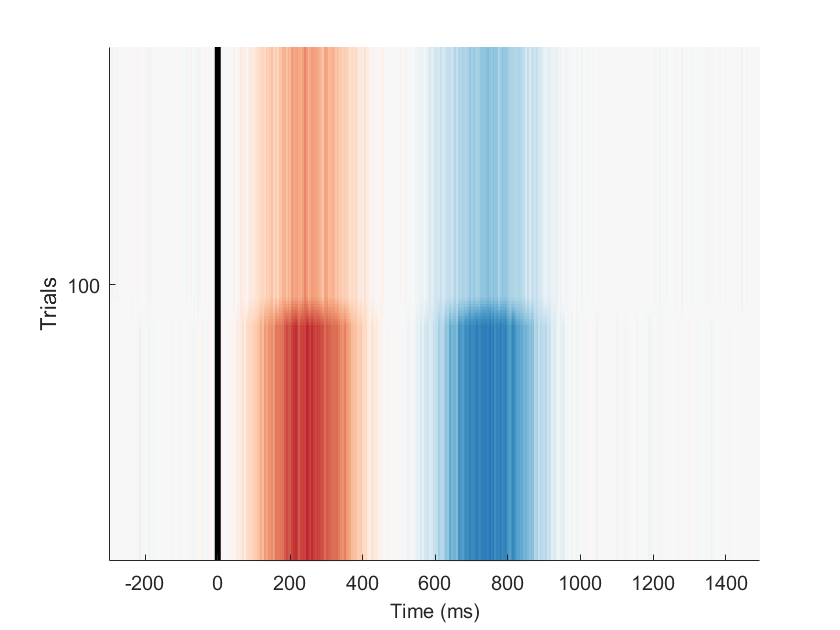

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'type','modelled','sort_by','stimulusType',cfg{:})

Interesting, only the first two peaks seem to be associated with the stimulus. Where do the later peaks come from?

## Sorting trials by event

Let's sort by the next trial onset. For this we have to specify `sort_time` to sort by something larger than 0.

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event stimulus, 185 epochs found
Sorting erpimage from event buttonpress forwards by field latency
Plotting input data as 185 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
85.41% of the trials (i.e., 158 out of 185) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 0, 25th ptile: 0, Median: 2, 75th ptile: 4, Max: 7

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-5,5].
Data will be plotted between -300 and 1495 ms.


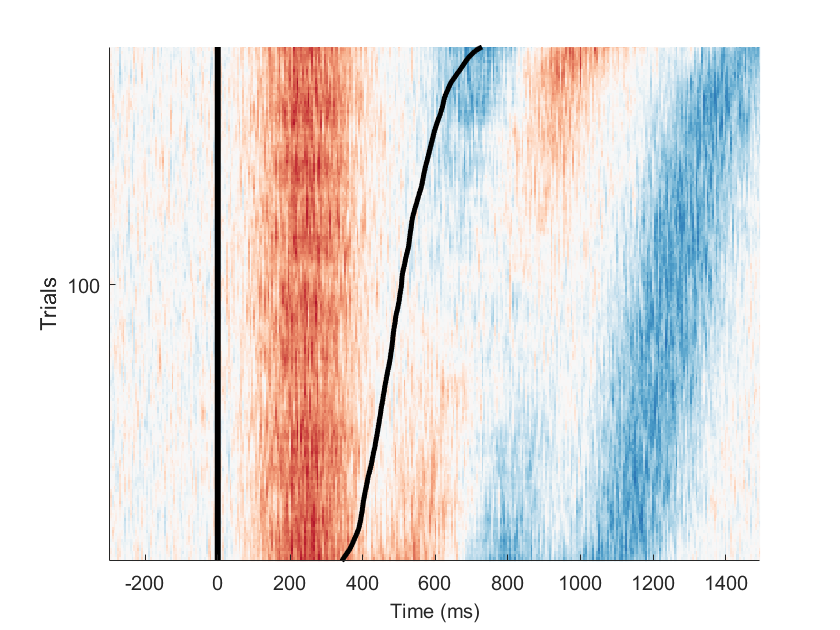

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'type','raw','sort_time',[eps 1.5],'sort_alignto',{'buttonpress'},cfg{:})

Aha! There buttonpress event elicits a clear timelocked analysis.

## Sorting trials by event AND condition

It is not straight forward to sort by two different sorting-criterions (here latency of following event and condition). Thus we split up the plot based on the condition at the "0" event.

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event stimulus, 185 epochs found
Sorting erpimage from event buttonpress forwards by field latency


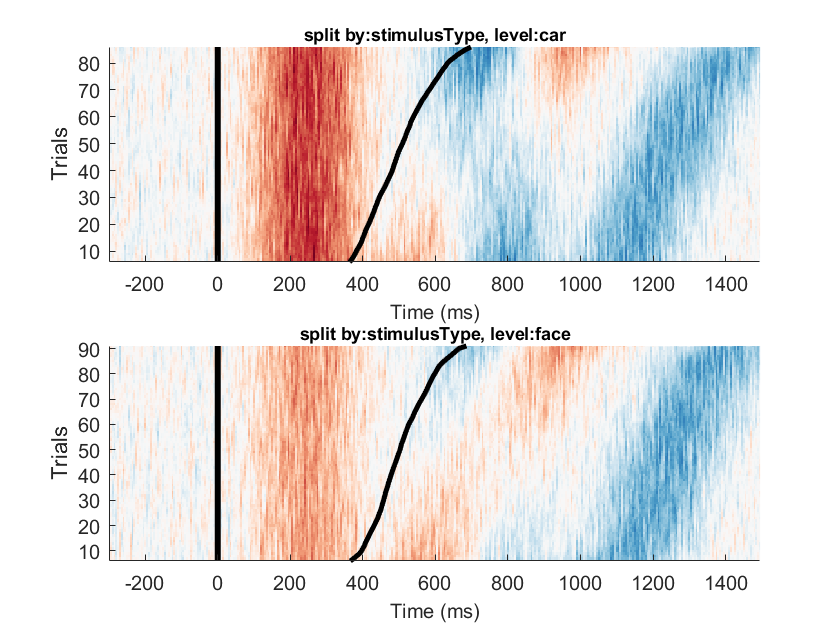

Plotting input data as 90 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
66.67% of the trials (i.e., 60 out of 90) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 0, 25th ptile: 0, Median: 0, 75th ptile: 2, Max: 4

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-5,5].
Data will be plotted between -300 and 1495 ms.
Output data will be 360 frames by 81 smoothed trials.
Outtrials: 6.00 to 86.00
Overplotting sorted sortvar on data.
Done.

Plotting input data as 95 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
67.37% of the trials (i.e., 64 out of 95) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 0, 25th ptile: 0, Median: 0, 75th ptile: 2, Max: 5

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decima

uf_erpimage(EEG,'type','raw','sort_time',[eps 1.5],'sort_alignto',{'buttonpress'},'split_by','stimulusType',cfg{:})

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event stimulus, 185 epochs found
Sorting erpimage from event buttonpress forwards by field latency


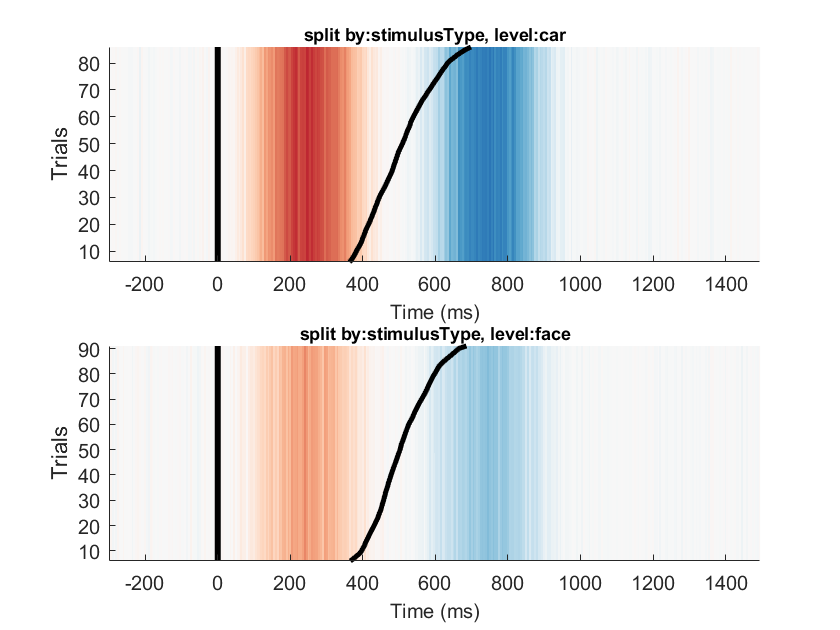

Plotting input data as 90 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
66.67% of the trials (i.e., 60 out of 90) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 0, 25th ptile: 0, Median: 0, 75th ptile: 2, Max: 4

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-5,5].
Data will be plotted between -300 and 1495 ms.
Output data will be 360 frames by 81 smoothed trials.
Outtrials: 6.00 to 86.00
Overplotting sorted sortvar on data.
Done.

Plotting input data as 95 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
67.37% of the trials (i.e., 64 out of 95) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 0, 25th ptile: 0, Median: 0, 75th ptile: 2, Max: 5

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decima

uf_erpimage(EEG,'type','modelled','sort_time',[eps 1.5],'sort_alignto',{'buttonpress'},'split_by','stimulusType',cfg{:})

## Plotting modelled-data with and without overlap

We can reintroduce overlap that we modelled, by a flag here. Thus `overlap=1` reflects $\hat{Y}$, the complete modelled signal, whereas `overlap=0` reflects the modelled signal, to a single event only

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event stimulus, 185 epochs found
Sorting erpimage from event stimulus forwards by field latency
Plotting input data as 185 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
100.00% of the trials (i.e., 185 out of 185) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 185, 25th ptile: 185, Median: 185, 75th ptile: 185, Max: 185

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-5,5].
Data will be plotted between -300 and 1495 ms.


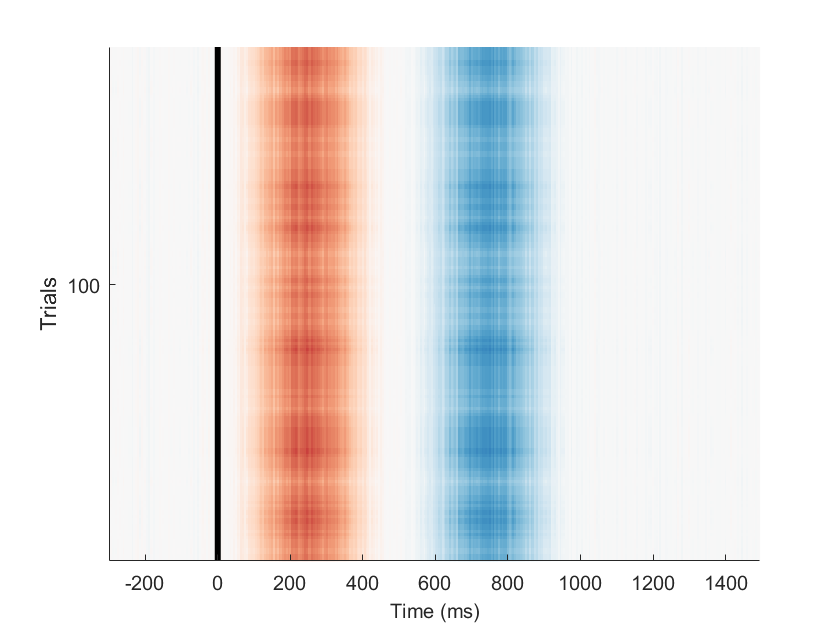

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'overlap',0,cfg{:})

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event stimulus, 185 epochs found
Sorting erpimage from event stimulus forwards by field latency
Plotting input data as 185 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
100.00% of the trials (i.e., 185 out of 185) have the same sortvar value as at least one other trial.
Distribution of number ties per un

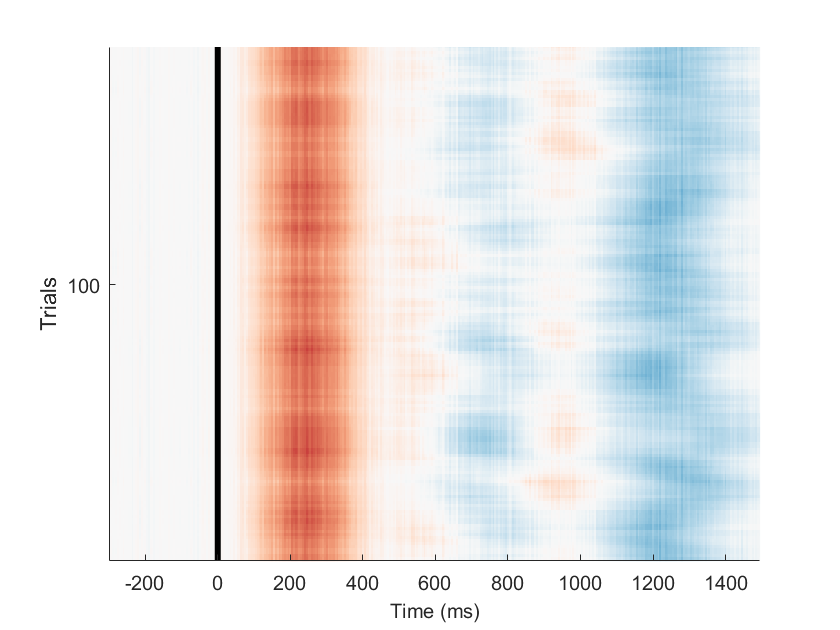

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'overlap',1,cfg{:})

## Looking at residuals

Like in any regression, it is possible to look at the residuals.

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
adding residuals
pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field us

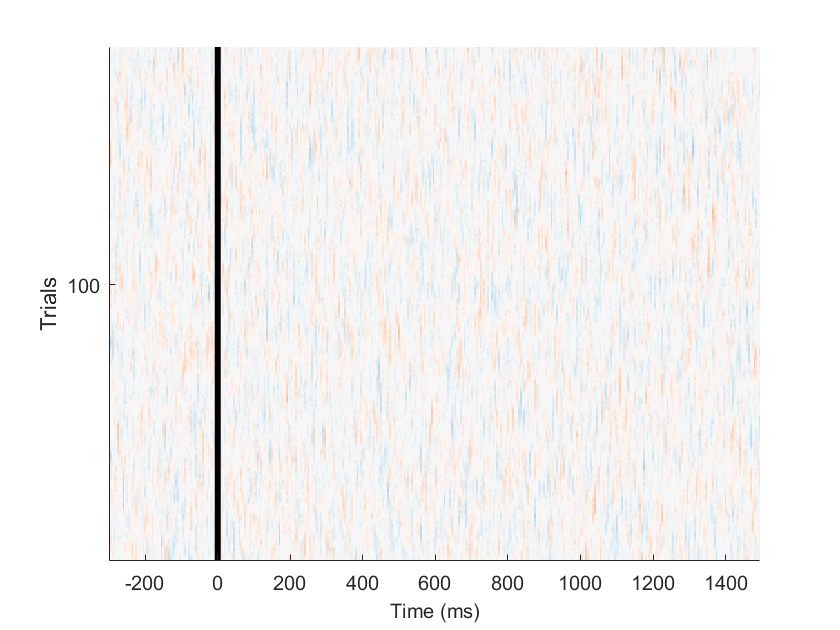

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'type','residual','overlap',1,cfg{:})

In this case, nothing really remains because we modelled everything that we simulated.

**Note** it is also to look at the residuals with `overlap=0. These would be the residuals of taking type=raw minus type=modelled without modelling the overlap in the latter. Thus all other events (or overlap with the same event-type) is not modeled`

## Adding residuals

What is sometimes a useful thing to do, is add the residuals based on the full model $\hat{Y}$ back to the modelled, but overlap corrected results. This gives a better single-trial-noise feeling. Note that by default the `overlap=1` residuals are added back.

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
adding residuals
pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Aligning erpimage to event stimulus, 185 epochs found
Sorting erpimage from event stimulus forwards by field latency
Plotting input data as 185 epochs of 360 frames sampled at 200.0 Hz.
Sorting data on input sortvar.
100.00% of the trials (i.e., 185 out of 185) have the same sortvar value as at least one other trial.
Distribution of n

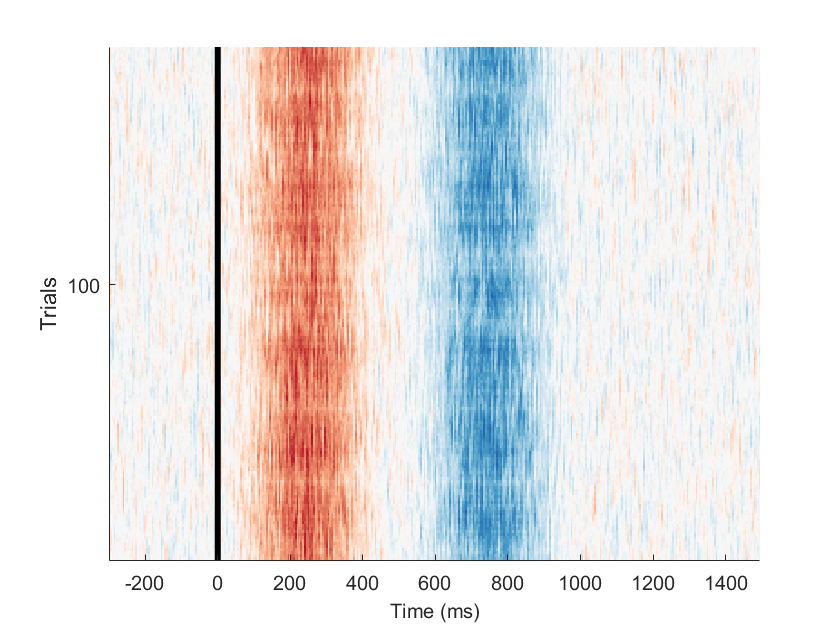

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'type','modelled','addResiduals',1,cfg{:})

## Keep & Remove / Partial Models

It is sometimes helpful to remove modelled events and/or remove effects. I.e. to simulate "what would it look like without" or to separate events better.

Thus we can look at what the **buttonpress** isolated looks like, when epoched to the **stimulus**

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Keeping the following predictors:
2_(Intercept), 
pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
adding residuals
pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data 

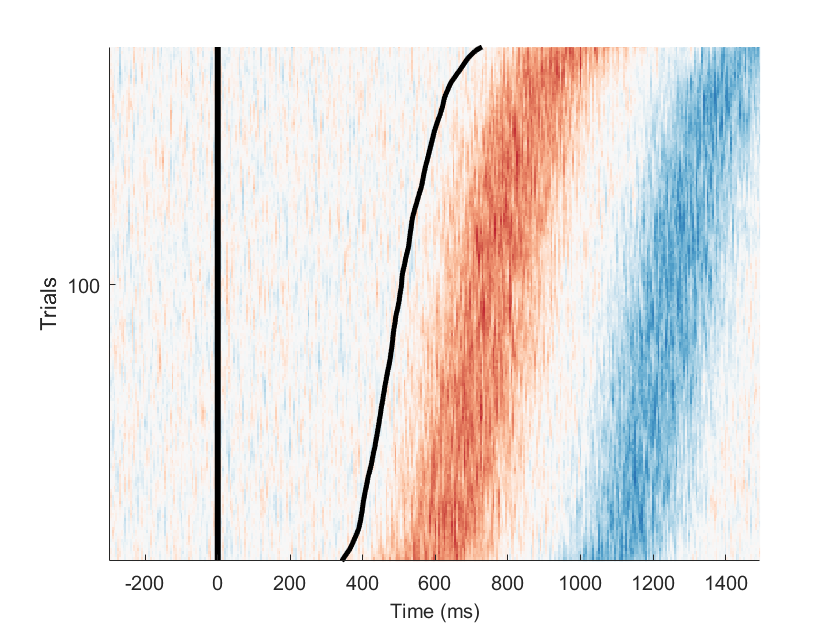

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'type','modelled','overlap',1,'keep',{'2_(Intercept)'},'sort_alignto','buttonpress','addResiduals',1,cfg{:})

Remove works similar but opposite. So we can remove the buttonpress event:

pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Removing the following predictors:
2_(Intercept), 
pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
adding residuals
pop_epoch():370 epochs selected
Epoching...
pop_epoch():370 epochs generated
eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset note: event field format 'stimulusType' made uniform
pop_epoch(): checking epochs for data

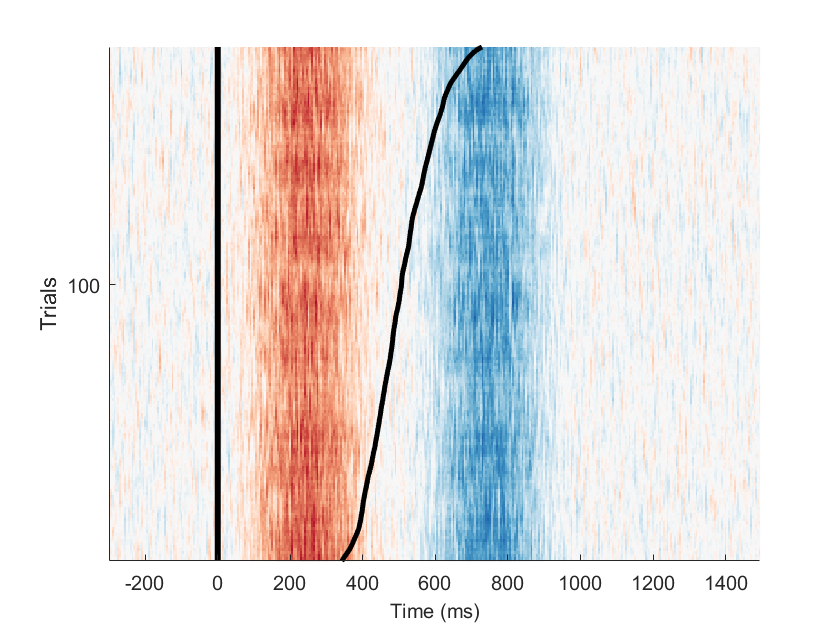

Output data will be 360 frames by 176 smoothed trials.
Outtrials: 6.00 to 181.00
Overplotting sorted sortvar on data.
Done.



uf_erpimage(EEG,'type','modelled','overlap',1,'remove',{'2_(Intercept)'},'sort_alignto','buttonpress','addResiduals',1,cfg{:})

Which, in this case, would be identical to plotting the modelled+residual activity of the stimulus event